- Calculul valorilor polinomului de interpolare Hermite cu noduri duble

x = [1.3,1.6,1.9];
f = [0.6200860, 0.4554022, 0.2818186];
fderiv = [-0.5220232, -0.5698959, -0.5811571];
result = interpolareHermite(x, f, fderiv, 1.5);

fprintf('Result: %.7f\n', result);

Result: 0.5118277


2. Reprezentați pe același grafic f si polinomul său de interpolare Hermite.

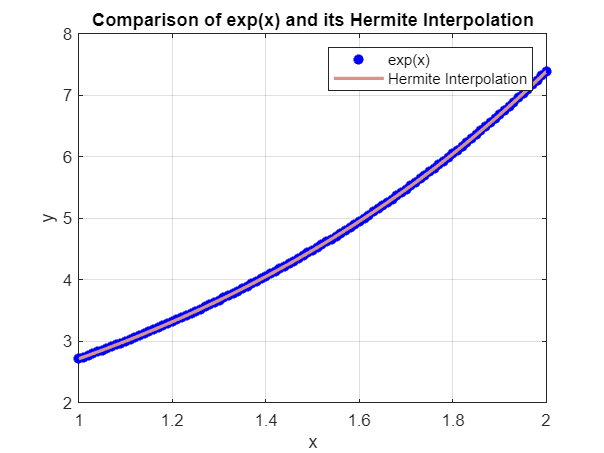

nodes = [0.8 1 1.4 1.8 2.1];
nodevals = exp(nodes);

t = 1 : 0.01 : 2;
res = interpolareHermiteMultiplePoints(nodes, nodevals, nodevals, t);
plot(t, exp(t), 'b*', 'LineWidth', 2); hold on;
plot(t, res, 'color', rand(1,3), 'LineWidth', 2); hold off;
legend('exp(x)', 'Hermite Interpolation');
xlabel('x');
ylabel('y');
title('Comparison of exp(x) and its Hermite Interpolation');

grid on;

3. Scrieți o rutină care reprezintă grafic o cubică parametrică Hermite (o

curbă care trece prin două puncte date și are în acele puncte tangente

date).

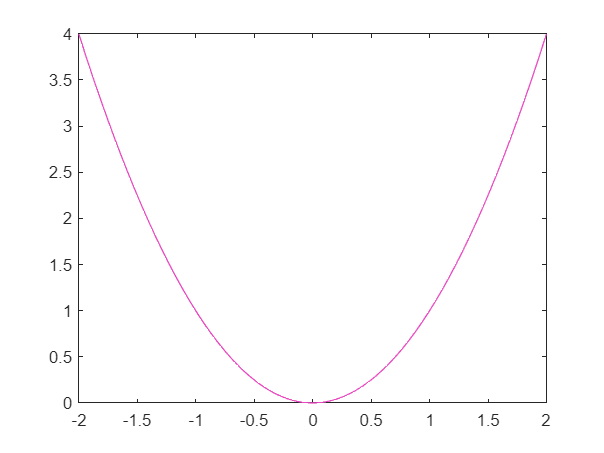

% functia x^2 pe intervalul [-2, 2]
x = [-2 2]; % punctele -2 si 2
f = [4 4]; 
fd = [-4 4];

t = -2 : 0.01 : 2;
res = interpolareHermiteMultiplePoints(x, f, fd, t);
plot(t, res, 'color', rand(1,3));

Probleme practice

1. Pentru f(x) = ex și nodurile de interpolare 0, 1, 2, aproximați f(0:25)

prin interpolare Hermite și comparați rezultatul cu cel obținut prin interpolare Lagrange.

l = interpolareLagrange([0 1 2], [exp(0) exp(1) exp(2)], 0.25) 

l = 1.1528

h = interpolareHermite([0 1 2], [exp(0) exp(1) exp(2)], [exp(0) exp(1) exp(2)], 0.25)

h = 1.2836

e = exp(0.25)

e = 1.2840

errLagrange = e - l

errLagrange = 0.1313

errHermite = e - h

errHermite = 3.8032e-04

2. Aproximați sin 0.34 utilizând interpolarea Hermite

x = [0.3, 0.32, 0.35];
sinx = [0.29552, 0.31457, 0.34290];
cosx = [0.95534, 0.94924, 0.93937];
result = interpolareHermite(x, sinx, cosx, 0.34);

fprintf('Result: %.7f\n', result);

Result: 0.3334889


sin(0.34)

ans = 0.3335

errHermite = sin(0.34) - result

errHermite = -1.7979e-06


x = [0.3, 0.32, 0.33, 0.35];
sinx = [0.29552, 0.31457, sin(0.33), 0.34290];
cosx = [0.95534, 0.94924, cos(0.33), 0.93937];
result = interpolareHermite(x, sinx, cosx, 0.34);

fprintf('Result: %.7f\n', result);

Result: 0.3334942


sin(0.34)

ans = 0.3335

errHermite = sin(0.34) - result

errHermite = -7.1369e-06

3. Un automobil care se deplasează pe un drum drept este cronometrat

în mai multe puncte. Datele de observație se dau în tabela de mai

jos. Utilizați interpolarea Hermite pentru a prevedea poziția și viteza

automobilului la momentul t = 10.

timp = [0,3,5,8,13];
dist = [0,225,383,623,993];
viteza = [75,77,80,74,72];
result = interpolareHermite(timp, dist, viteza, 10);

fprintf('Result: %.7f\n', result);

Result: 750.0000000
